# Clasificación de regiones en imágenes

En un sistema de reconocimiento se tienen 4 etapas principales que son el sensado, preprocesamiento (filtros, segmentación), extracción de características y clasificación de patrones. El objetivo de la clasificacion de patrones es asignar a una clase a los objetos de una escena. Un patrón es un arreglo espacial de características $\mathit{\mathbf{x}}$, es decir, un arreglo de descriptores cuantitativos de atributos $x_i$. 


$$\mathit{\mathbf{x}}=\left\lbrack x_1 ,{\;x}_2 ,{\;x}_{3\;} \;\ldotp \ldotp \ldotp x_n \right\rbrack$$


    Un patron se puede apreciar como un espacio Euclidiano de *n* dimensiones. Una clase de patrones se puede ver como una región multiespacial o una hipernube, en el espacio de patrones. Idealmente cada hipernube o clase, se encuentra alejada de las demás, sin embargo, esto no siempre sucede, para elllo se requieren utilizar distintas técnicas para la clasificación, estas se pueden dividir en 3 categorias principales:

- Emparejamiento de patrones (vecinos próximos).

- Formulación mediante optimización estadística (clasificación Bayesiana).

- Utilización de redes neuronales.

    Las primeras 2 técnicas son utilizadas cuando la naturaleza de los datos están bien entedidas, es decir existe una relación entre las caracterísiticas y el diseño del clasificador. Los procedimientos basados en redes neuronales requieren menor conocimento, estas se utilizan en aplicaciones donde las caracteristicas se pueden aprender del sistema en tiempo de operación. En los 3 procedimientos es necesario determinar una serie de parámetros, los cuales pueden ser especificados por el usuario o pueden ser aprendidos de los patrones del reconocimiento.

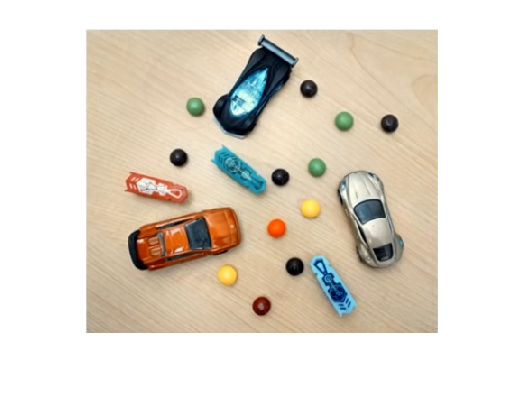

clear all;
I = imread('CarroCanica.png');
figure
imshow(I)

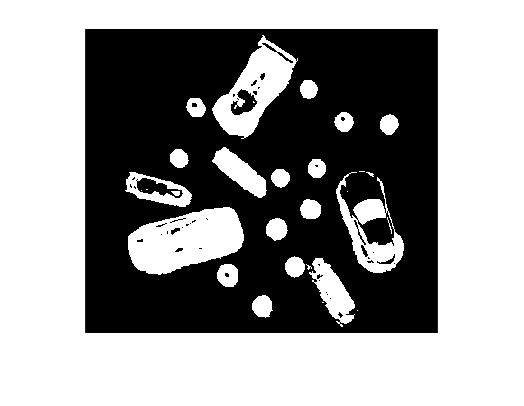

Iseg = imbinarize(I);
BW = ~(Iseg(:,:,1) & Iseg(:,:,2) & Iseg(:,:,3));

figure
imshow(BW)

se = strel('disk',1);       BW = imclose(BW,se);
se = strel('disk',1);       BW = imopen(BW,se);
BW = imfill(BW, 'holes');

s = regionprops('table',BW,'Centroid','Circularity','MajoraxisLength','MinoraxisLength',"Eccentricity")

s = 22×5 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Circularity
    ________________    _______________    _______________    ____________    ___________

    80.858    179.27        80.618             27.948           0.93799         0.62282  
    112.18    235.05         139.7             62.236           0.89528         0.76295  
    104.71    144.01        22.092             19.776            0.4457          1.0728  
    123.42      87.5        23.344             19.826            0.5279          1.0703  
    188.63    67.626        125.01             55.127           0.89752         0.66518  
    172.66    159.52        76.753             25.705           0.94225         0.65325  
    158.83    273.84        26.111             24.185           0.37696          1.0587  
    

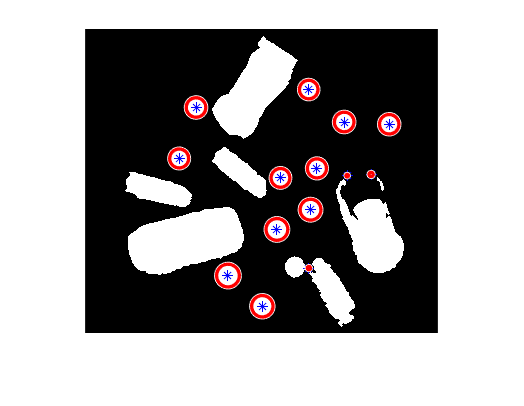

figure
imshow(BW);
hold on;
  
for i = 1:length(s.Circularity)
    radio(i) = mean([s.MajorAxisLength(i), s.MinorAxisLength(i)])/2;
    if s.Circularity(i) > 1 
       plot(s.Centroid(i,1), s.Centroid(i,2),'b*');
       viscircles(s.Centroid(i,:),radio(i));
    end
end
hold off;

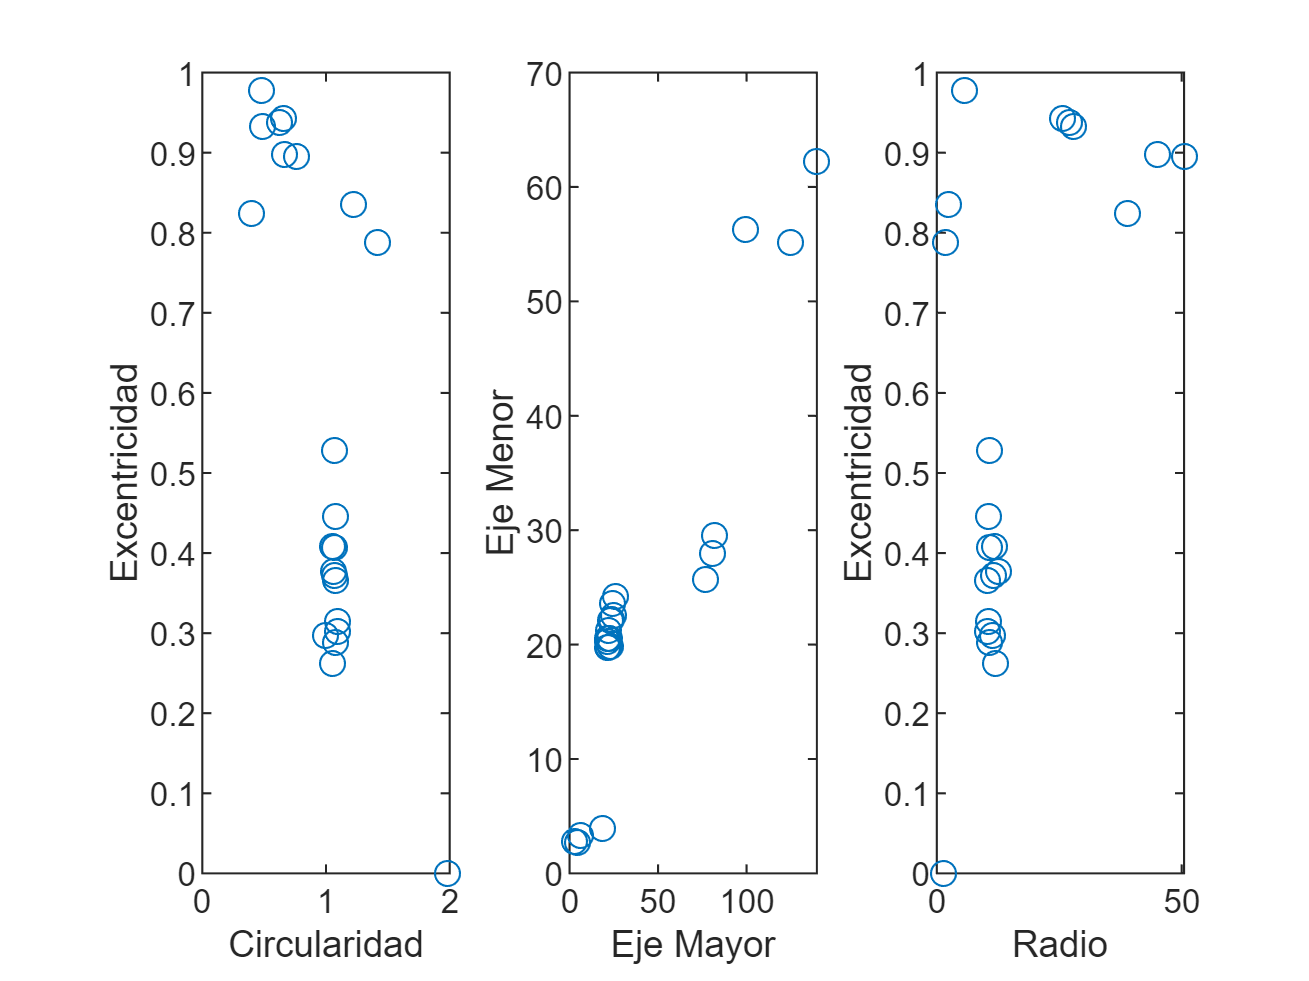

figure
subplot(1,3,1);
plot(s.Circularity, s.Eccentricity,'Marker',"o",'LineStyle',"none");
xlabel('Circularidad');        ylabel('Excentricidad');
subplot(1,3,2);
plot(s.MajorAxisLength, s.MinorAxisLength,'Marker',"o",'LineStyle',"none");
xlabel('Eje Mayor');        ylabel('Eje Menor');
subplot(1,3,3);
plot(radio, s.Eccentricity,'Marker',"o",'LineStyle',"none");
xlabel('Radio');        ylabel('Excentricidad');

    Como ejemplos de arreglos de patrones, pueden ser la circularidad, excentricidad

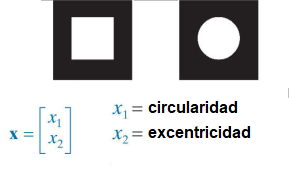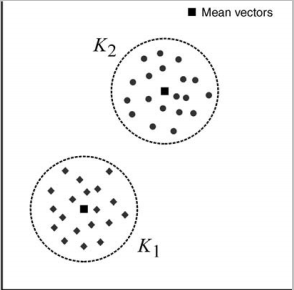

    Los momentos estadísticos, como son los momentos invariantes RST de Hu

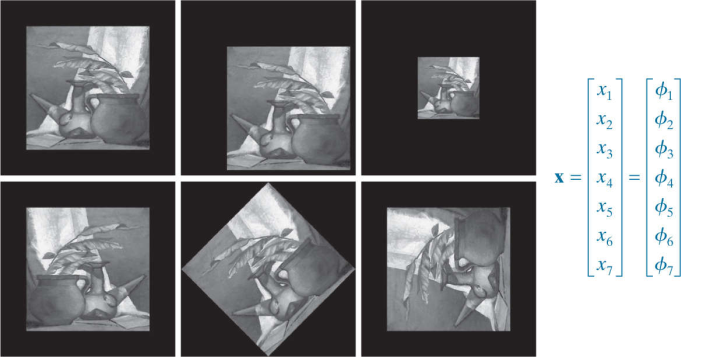

## Técnicas de clasificación basadas en los vecinos más próximos. 

También llamada clasificación por distancia mínima, se tiene un vector ${\mathit{\mathbf{m}}}_{j\;}$que es el centroide de alguna clase $\omega_{j\;}$, 


$$D_{j\;} \left(\mathit{\mathbf{x}}\right)=\left\|\mathit{\mathbf{x}}-{\mathit{\mathbf{m}}}_j \right\|$$


    Recordando la norma Euclidiana


$${\left\|\mathit{\mathbf{x}}-{\mathit{\mathbf{m}}}_j \right\|}^{2\;} =\left(\mathit{\mathbf{x}}-{\mathit{\mathbf{m}}}_j \right)\dot{\cdot \left(\mathit{\mathbf{x}}-{\mathit{\mathbf{m}}}_j \right)} =\mathit{\mathbf{x}}\cdot \mathit{\mathbf{x}}-2\mathit{\mathbf{x}}\cdot \;{\mathit{\mathbf{m}}}_j +{\mathit{\mathbf{m}}}_j \cdot \;{\mathit{\mathbf{m}}}_j =\mathit{\mathbf{x}}\cdot \mathit{\mathbf{x}}-2\left(\mathit{\mathbf{x}}\cdot \;{\mathit{\mathbf{m}}}_j -\frac{1}{2}{\mathit{\mathbf{m}}}_j \cdot \;{\mathit{\mathbf{m}}}_j \right)$$


    Dado que se busca el mínimo de $D_{j\;} \left(\mathit{\mathbf{x}}\right)$, es similar a encontrar el máximo de $d_j \left(\mathit{\mathbf{x}}\right)=\mathit{\mathbf{x}}\cdot \;{\mathit{\mathbf{m}}}_j -\frac{1}{2}{\mathit{\mathbf{m}}}_j \cdot \;{\mathit{\mathbf{m}}}_j$, llamado el *discriminante*, ya que $\mathit{\mathbf{x}}\cdot \mathit{\mathbf{x}}>0$. Entonces sí $d_{j\;} \left(\mathit{\mathbf{x}}\right)>d_i \left(\mathit{\mathbf{x}}\right)$, $\mathit{\mathbf{x}}\;\epsilon \;\omega_{j\;}$, es decir, se realiza una busqueda del máximo entre las clases $\max_{j\;} \left(d_{j\;} \left(x\right)\right)$.

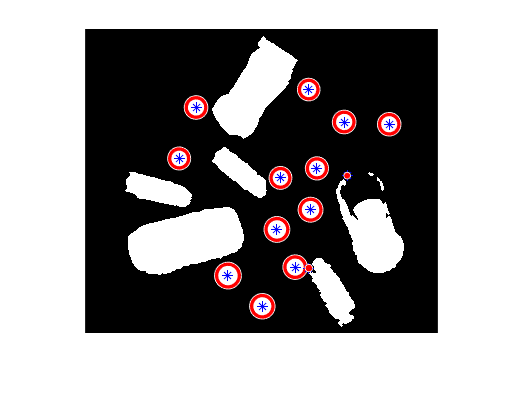

mu_1 = [1.1, 0.4];
mu_2 = [0.8, 0.9];

x(:,:) = [s.Circularity'; s.Eccentricity'];

d_1 = mu_1*x - 0.5* mu_1*mu_1';
d_2 =  mu_2*x - 0.5* mu_2*mu_2';

figure;
imshow(BW);
hold on;

k = 1;
l = 1;
for j = 1:length(d_1)
    if d_1(j) > d_2(j)
       x_1(:,k) =  x(:,j);
       k = k+1;
       plot(s.Centroid(j,1), s.Centroid(j,2),'b*');
       viscircles(s.Centroid(j,:),radio(j));
    else
       x_2(:,l) =  x(:,j);
       l = l+1; 
    end
end
hold off;

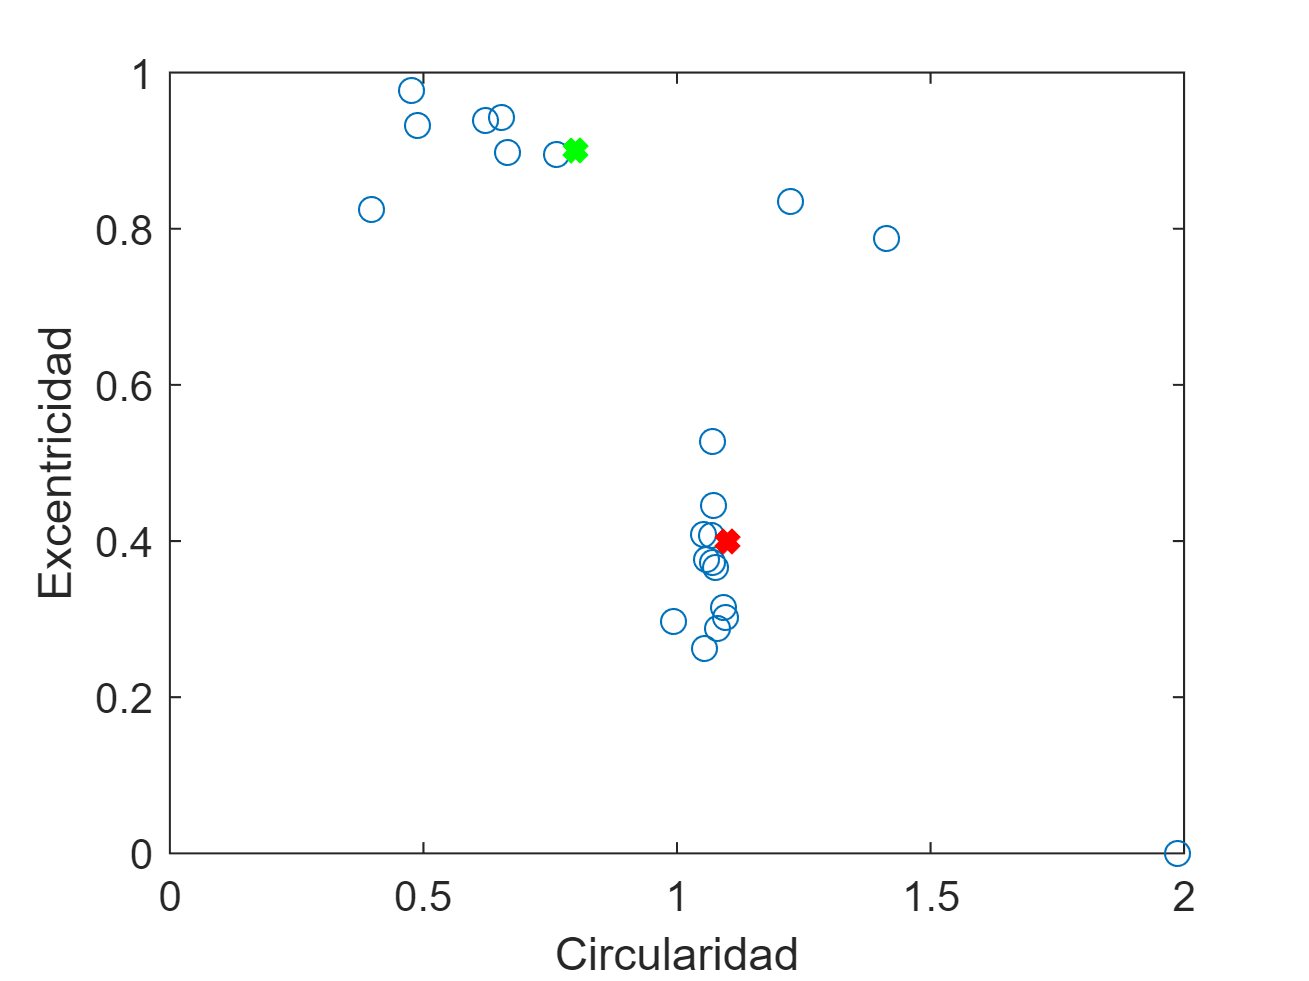

%Nuevo centroide
figure
plot(s.Circularity, s.Eccentricity, 'Marker',"o",'LineStyle',"none");
xlabel('Circularidad');        ylabel('Excentricidad');
hold on; 
plot(mu_1(1), mu_1(2),'Marker',"x",'LineStyle',"none", 'Color','r', 'LineWidth',3);
plot(mu_2(1), mu_2(2),'Marker',"x",'LineStyle',"none", 'Color','g', 'LineWidth',3);

hold off;

    Tambien es posible definr una frontera entre dos clases, esto se puede definir cuando los discriminantes son iguales


$$\begin{array}{l}
d_{j\;} \left(x\right)=d_i \left(x\right)\\
d_{j\;} \left(x\right)-d_i \left(x\right)=0\\
\mathit{\mathbf{x}}\cdot \;{\mathit{\mathbf{m}}}_j -\frac{1}{2}{\mathit{\mathbf{m}}}_j \cdot \;{\mathit{\mathbf{m}}}_j -\mathit{\mathbf{x}}\cdot \;{\mathit{\mathbf{m}}}_i +\frac{1}{2}{\mathit{\mathbf{m}}}_i \cdot \;{\mathit{\mathbf{m}}}_i =0
\end{array}$$


## Clasificación Bayesiana

La probabilidad de que un vector patrón $\mathit{\mathbf{x}}$ provenga de la clase ${\omega \;}_{i\;} \;$se denota por $p\left({\omega \;}_{i\;} \left|\mathit{\mathbf{x}}\right.\right)\ldotp$ Si el clasificador de patrones decide que $\mathit{\mathbf{x}}$ proviene de clase ${\omega \;}_j$cuando en realidad proviene de ${\omega \;}_{i\;}$ incurre en una *pérdida*, denotado por $L_{\textrm{ij}}$. Porque el patrón $\mathit{\mathbf{x}}$ puede pertenecer a cualquier de posibles clases, la pérdida promedio incurrida al asignar $\mathit{\mathbf{x}}$ a la clase es


$$r_j \left(\mathit{\mathbf{x}}\right)=\sum_k^C L_{\textrm{kj}}$$

$$p\left({\omega \;}_{k\;} \left|\mathit{\mathbf{x}}\right.\right)$$


La cantidad $r_j \left(\mathit{\mathbf{x}}\right)$se denomina *riesgo o pérdida promedio condicional* en la terminología de la teoría de decisiones. Podemos utilizar la regla de Bayes $p\left({\omega \;}_{k\;} \left|\mathit{\mathbf{x}}\right.\right)=\frac{p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)}{\;p\left(\mathit{\mathbf{x}}\right)}$, para poder escribir la ecuacion de riesgo como


$$r_j \left(\mathit{\mathbf{x}}\right)=\frac{1}{\;p\left(\mathit{\mathbf{x}}\right)}\sum_k^C L_{\textrm{kj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)$$


donde $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)$ es la función de densidad de probabilidad de los patrones de clase ${\omega \;}_{k\;}$ y $p\left(\omega_k \right)$ es la probabilidad de ocurrencia de clase, tambien llamada probabilidad a priori. Dado que $\frac{1}{\;p\left(\mathit{\mathbf{x}}\right)}$ es positivo y común a todas las ecuaciones de *riesgo *se puede quitar de la ecuación, sin afectar la clasificación. La expresión para la *pérdida promedio* se reduce a:


$$r_j \left(\mathit{\mathbf{x}}\right)=\sum_k^C L_{\textrm{kj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)$$


Dado un patrón desconocido, el clasificador tiene posibles clases $C\;$entre las que elegir. Se calculan $r_{1\;} \left(\mathit{\mathbf{x}}\right),{\;r}_2 \left(\mathit{\mathbf{x}}\right),{\;r}_{3\;} \left(\mathit{\mathbf{x}}\right)\;\ldotp \ldotp \ldotp r_C \left(\mathit{\mathbf{x}}\right)$para cada patrón $\mathit{\mathbf{x}}$, se asigna el patrón a la clase que tiene la menor *pérdida promedio total *o menor* riesgo*, El clasificador que minimiza la *pérdida promedio total* se llama *clasificador de Bayes*. Se asigna un patrón desconocido $\mathit{\mathbf{x}}\;$a la clase $\omega_i$ si $\left.\left.{r\left(\omega \right.}_i \right)<{r\left(\omega \right.}_j \right)$. 


$$r_i \left(\mathit{\mathbf{x}}\right)<r_j \left(\mathit{\mathbf{x}}\right)$$



$$\sum_k^C L_{ki} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)<\sum_l^C L_{lj} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_l \right.\right)\;p\left(\omega_l \right)$$


Para poder asignar el patrón $\mathit{\mathbf{x}}$a la clase ${\omega \;}_i$, debemos comenzar a definir cada uno de los térmimos de la ecuación anteiror ($L_{\textrm{ki}}$,$p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right),\;p\left(\omega_k \right)$ ). Comencemos por la *función de pérdida *$L_{\textrm{ki}}$*, * esta función nos ayuda a determinar sí tomamos una decisión correcta. Por definición, a una decisión correcta generalmente se le asigna un valor de 0, y a una decisión incorrecta generalmente se le asigna un valor de 1. Realizamos una clasificación correcta, es decir  una decisión correcta, cuando $j=i$, es decir se clasifica al patrón $\mathit{\mathbf{x}}$ a la clase ${\omega \;}_i$, entonces $L_{\textrm{ii}} =0$ y se realiza una clasificación incorrecta cuando$j\not= \;i$, entonces $L_{\textrm{ij}} =1\ldotp$La *función de pérdida *definida como se hizo anteriormentes, se le llama *función de pérdida 1-0,* se puede expresar como:


$$L_{\textrm{ij}} =1-\delta {\;}_{\textrm{ij}}$$


donde $\delta {\;}_{\textrm{ij}} =1$ si  $j=i$ y $\delta {\;}_{\textrm{ij}} =0$ si $j\not= i$. Sustituyendo la ecuación anterior en el modelo del *pérdida promedio total* se obtiene


$$r_j \left(\mathit{\mathbf{x}}\right)=\sum_k^C \left(1-\delta {\;}_{\textrm{kj}} \right)\;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)=\sum_k^C p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)-\sum_k^C \delta {\;}_{\textrm{kj}} p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)$$


Pero por Bayes sabemos que $p\left(\mathit{\mathbf{x}}\right)=\sum_k^C p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)$, ademas por la definición de la función $\delta {\;}_{\textrm{ij}}$


$$\sum_k^C \delta {\;}_{\textrm{kj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{\;} \right.\right)\;p\left(\omega_k \right)=\delta {\;}_{1j} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_1 \right.\right)\;p\left(\omega_1 \right)+\delta {\;}_{2j} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_2 \right.\right)\;p\left(\omega_k \right)\ldotp \ldotp \ldotp +\;\delta {\;}_{\textrm{jj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{j\;} \right.\right)\;p\left(\omega_j \right)\ldotp \ldotp \ldotp +\;\delta {\;}_{\textrm{Cj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_C \right.\right)\;p\left(\omega_C \right)$$



$$\sum_k^C \delta {\;}_{\textrm{kj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{\;} \right.\right)\;p\left(\omega_k \right)=0\cdot p\left(\mathit{\mathbf{x}}\left|{\omega \;}_1 \right.\right)\;p\left(\omega_1 \right)+0\cdot p\left(\mathit{\mathbf{x}}\left|{\omega \;}_2 \right.\right)\;p\left(\omega_k \right)\ldotp \ldotp \ldotp +1\cdot p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{j\;} \right.\right)\;p\left(\omega_j \right)\ldotp \ldotp \ldotp +0\cdot p\left(\mathit{\mathbf{x}}\left|{\omega \;}_C \right.\right)\;p\left(\omega_C \right)$$



$$\sum_k^C \delta {\;}_{\textrm{kj}} \;p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{k\;} \right.\right)\;p\left(\omega_k \right)=$$

$$p\left(\mathit{\mathbf{x}}\left|{\omega \;}_{j\;} \right.\right)\;p\left(\omega_j \right)$$


la ecuación de *pérdida promedio total *se reduce a:


$$r_j \left(\mathit{\mathbf{x}}\right)=p\left(\mathit{\mathbf{x}}\right)-p\left(\mathit{\mathbf{x}}\left|{\omega \;}_j \right.\right)\;p\left(\omega_j \right)$$


De este modo *clasificador de Bayes* se expresa como:


$$r_i \left(\mathit{\mathbf{x}}\right)<r_j \left(\mathit{\mathbf{x}}\right)$$



$$p\left(\mathit{\mathbf{x}}\right)-p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)\;p\left(\omega_i \right)<p\left(\mathit{\mathbf{x}}\right)-p\left(\mathit{\mathbf{x}}\left|{\omega \;}_j \right.\right)\;p\left(\omega_j \right)$$



$$-p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)\;p\left(\omega_i \right)<-p\left(\mathit{\mathbf{x}}\left|{\omega \;}_j \right.\right)\;p\left(\omega_j \right)$$



$$p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)\;p\left(\omega_i \right)>p\left(\mathit{\mathbf{x}}\left|{\omega \;}_j \right.\right)\;p\left(\omega_j \right)$$


Por lo tanto, el *clasificador de Bayes* para una *función de pérdida 0-1,* se puede pensar como *funciones de decisión* 


$$d_i \left(\mathit{\mathbf{x}}\right)=p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)\;p\left(\omega_i \right)$$


se asigna un patrón $\mathit{\mathbf{x}}$ a la clase ${\omega \;}_i$ si $d_i \left(\mathit{\mathbf{x}}\right)>d_j \left(\mathit{\mathbf{x}}\right)$. Este es exactamente el mismo proceso descrito en el *discriminante por vecinos próximos*, pero ahora se trata de *funciones de decisión, *sin embargo, para estas funciones se ha demostrado que son óptimas en el sentido de que minimizan la *pérdida promedio* en una *clasificación errónea*.

Para que se mantenga la optimalidad de las* funciones de decisión de Bayes*, las funciones de densidad de probabilidad de los patrones  en cada clase $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)$, así como la probabilidad de ocurrencia de cada clase $p\left(\omega_i \right)$, se tienen que definir o estimar. Por ejemplo, si todas las clases tienen la misma probabilidad de que ocurran, entonces $p\left(\omega_i \right)=\frac{1}{C}$.Incluso si esta condición no es cierta, estas probabilidades generalmente se pueden inferir del conocimiento del problema. La estimación de las funciones de densidad de probabilidad $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)$ es más difícil. Si los vectores de patrón son $n$-dimensionales, entonces $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)$ es una función de $n$ variables. Si no se conoce la forma de $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)$, la estimación requiere el uso de una estimación con métodos multivarianble. Estos métodos son difíciles de aplicar en la práctica, por estas razones, los usos del clasificador de Bayes a menudo se basan en una expresión analítica para las funciones de densidad. Esto, a su vez, reduce el problema, la función de densidad de probabilidad Gaussiana, es la más utilizada.

Para empezar el análisis comencemos con un problema 1-D, es decir $n$=1, que involucra dos clases de patrones, $\omega_1 ,\omega_{2\;} ;\;C=2$, con densidades gaussianas, con sus medias $\mu_1 ,{\;\mu }_2$ y desviaciones estándar ${\sigma \;}_1 ,{\;\sigma \;}_2$, para cada clase respectivamente. Las funciones de decisión de Bayes tienen la forma


$$d_i \left(\mathit{\mathbf{x}}\right)=p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)\;p\left(\omega_i \right)$$



$$p\left(\mathit{\mathbf{x}}\left|{\omega \;}_i \right.\right)=$$

$$\frac{1}{\sqrt{\;2\pi \;}\sigma_{i\;} \;}e^{-\frac{{\left(x-\mu {\;}_{i\;} \right)}^2 }{2{{\;\sigma_{i\;} }^{2\;} \;}_{\;} }}$$



$$d_i \left(\mathit{\mathbf{x}}\right)=\left(\frac{1}{\sqrt{\;2\pi \;}\sigma_{i\;} \;}e^{-\frac{{\left(x-\mu {\;}_{i\;} \right)}^2 }{2{{\;\sigma_{i\;} }^{2\;} \;}_{\;} }} \right)\;p\left(\omega_i \right)$$


para este caso los patrones ahora son escalares, denotados por $\mathit{\mathbf{x}}$. En la siguiente figura se muestra este caso.

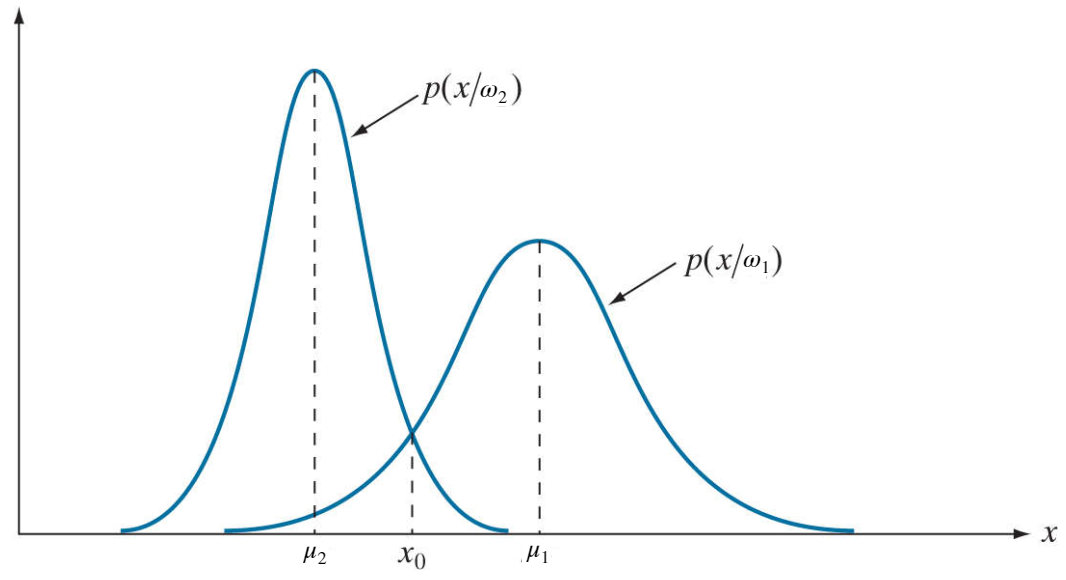

El límite entre las dos clases es un solo punto ${\mathit{\mathbf{x}}}_0$, llamado *punto de decisión*. Cualquier patrón (punto) a la derecha de ${\mathit{\mathbf{x}}}_0$ se clasifica como perteneciente a la clase $\omega_1$, debido a que $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_1 \right.\right)>p\left(\mathit{\mathbf{x}}\left|{\omega \;}_2 \right.\right)$. De manera similar, cualquier patrón a la izquierda de ${\mathit{\mathbf{x}}}_0$ se clasifica como perteneciente a la clase $\omega_2$, ya que $p\left(\mathit{\mathbf{x}}\left|{\omega \;}_2 \right.\right)>p\left(\mathit{\mathbf{x}}\left|{\omega \;}_1 \right.\right)$.

En el caso n-dimensional, la densidad gaussiana de los vectores en la $j$-ésima clase de patrón tiene la forma


$$p\left(\mathit{\mathbf{x}}\left|\omega_i \right.\right)=\left(\frac{1}{{\left(2\pi \;\right)}^{\frac{n}{2}} \left|\Sigma_{i\;} {\left|\right.}^{\frac{1}{2}} \;\right.}e^{-\frac{1}{2}{\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)}^T {\Sigma^{-1} }_{i\;} \;\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)} \right)\;$$


donde cada densidad se determina completamente por su vector de valores medios $\mu_{i\;}$ y matriz de covarianza $\Sigma_{i\;}$ que se definen como


$$\mu_{i\;} ={\mathrm{E}}_{i\;} \left\lbrace \mathit{\mathbf{x}}\right\rbrace$$


y


$$\Sigma_{i\;} ={\mathrm{E}}_{i\;} \left\lbrace \left(\mathit{\mathbf{x}}-\mu_{i\;} \right){\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)}^T \right\rbrace ={\mathrm{E}}_{i\;} \left\lbrace \mathit{\mathbf{x}}\;{\mathit{\mathbf{x}}}^T \right\rbrace -\mu_{i\;} \;\mu_{i\;}^T$$


donde es el valor esperado ${\mathrm{E}}_{i\;} \left\lbrace \right\rbrace$ del argumento sobre los patrones de clase $\omega_i$, $n$ es la dimensionalidad de los vectores de patrón y  $\left|\Sigma_{i\;} \right|$es el determinante de la matriz. Se puede aproximar el valor esperado ${\mathrm{E}}_{i\;} \left\lbrace \right\rbrace$ por el promedio de la muestra produce una estimación del vector medio y la matriz de covarianza:


$$\mu_{i\;} =\frac{1}{n_{\omega {\;}_i } }\sum_{\mathit{\mathbf{x}}\;\epsilon \;\omega_i } \mathit{\mathbf{x}}$$


y


$${\Sigma \;}_{i\;} =\frac{1}{n_{\omega {\;}_i } }\sum_{\mathit{\mathbf{x}}\;\epsilon \;\omega_i } \mathit{\mathbf{x}}\;{\mathit{\mathbf{x}}}^T -\mu_{i\;} \;\mu_{i\;}^T$$


donde $n_{\omega {\;}_i }$ es el número de vectores de patrón de muestra de la clase  $\omega_i$ 

La matriz de covarianza es simétrica y semidefinida positiva. Su $k$-ésimo elemento diagonal es la varianza del $k$-ésimo elemento de los vectores patrón. El $\textrm{kj}$elemento de la matriz fuera de la diagonal es la covarianza de los elementos ${\mathit{\mathbf{x}}}_k$ y ${\mathit{\mathbf{x}}}_{j\;}$ en estos vectores. Con la forma exponencial de la densidad gaussiana, se puede trabajar con el logaritmo natural de esta *función de decisión*, que es más conveniente. 


$$\ln \left(d_i \left(\mathit{\mathbf{x}}\right)\right)=\ln \left(p_i \left(\mathit{\mathbf{x}}\left|\omega_i \right.\right)p\left(\omega_i \right)\right)=\ln \left(\left(\frac{1}{{\left(2\pi \;\right)}^{\frac{n}{2}} \left|\Sigma_{i\;} {\left|\right.}^{\frac{1}{2}} \;\right.}e^{-\frac{1}{2}{\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)}^T {\Sigma^{-1} }_{i\;} \;\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)} \right)p\left(\omega_i \right)\right)\;$$



$$\ln \left(d_i \left(\mathit{\mathbf{x}}\right)\right)=$$

$$-\frac{n}{2}\ln \left(2\pi \right)-\ln \left(\left|\Sigma_{i\;} \right|\right)-\frac{1}{2}{\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)}^T {\Sigma^{-1} }_{i\;} \;\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)+\ln \left(p\left(\omega_i \right)\right)$$


En términos de optimización la ecuación anterior tiene el mismo punto optimo, porque el logaritmo es una función que aumenta monótonamente. Es decir, si $f\left(x\right)>0$, obtener el máximo de $\max \;\left(f\left(x\right)\right)$ y $\max \left(\ln \left(f\left(x\right)\right)\right)$ es idéntico, de cálculo diferencial $\;\frac{d\;f\left(x\right)}{\textrm{dx}}=0$, y $\frac{d\left(\ln \left(f\left(x\right)\right)\right)}{\textrm{dx}}=\frac{1}{f\left(x\right)}\frac{d\;f\left(x\right)}{\textrm{dx}}=0$, dado que $f\left(x\right)>0$, se comprueba que es el mismo punto. Omitiendo los términos constantes, ya que estos no cambian en la optimización, tenemos una nueva *función de decisión de Bayes* bajo la condición de una *función de pérdida* 0-1.


$$d_i \left(\mathit{\mathbf{x}}\right)=$$

$$-\ln \left(\left|\Sigma_{i\;} \right|\right)-$$

$$\frac{1}{2}{\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)}^T {\Sigma^{-1} }_{i\;} \;\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)+\ln \left(p\left(\omega_i \right)\right)$$


Como una primera aproximación, podemos definir que todas las matrices de covarianza son iguales $\Sigma_{i\;} =\Sigma$, entonces para al expandir el segundo termino del lado derecho y eleminando las constantes, debido a la optimización.


$$d_i \left(\mathit{\mathbf{x}}\right)=$$

$$-\ln \left(\left|\Sigma \right|\right)-$$

$$\frac{1}{2}{\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)}^T \Sigma^{-1\;} \;\left(\mathit{\mathbf{x}}-\mu_{i\;} \right)+\ln \left(p\left(\omega_i \right)\right)$$



$$d_i \left(\mathit{\mathbf{x}}\right)=$$

$${\mathit{\mathbf{x}}}^T \Sigma {\;}^{-1} \mu_{i\;} -\frac{1}{2}{\mu_{i\;} }^T \Sigma^{-1\;} \;\mu_{i\;} +\ln \left(p\left(\omega_i \right)\right)$$


que son funciones de decisión lineal (hiperplanos). Si, además, donde $\Sigma =I$, es decir,  la matriz de identidad, y también si las clases son igualmente probables $\omega_i$, entonces podemos descartar el término porque sería el mismo para todos los valores de $i$. La ecuación de *decisión de Bayes *se convierte en


$$d_i \left(\mathit{\mathbf{x}},t=0\right)=$$

$${\mathit{\mathbf{x}}}^T \mu_{i\;} \left(t=0\right)-\frac{1}{2}{\mu_{i\;} \left(t=0\right)}^T \;\mu_{i\;} \left(t=0\right)$$


La cual es una *función de decisión* para un clasificador de distancia mínima. Por tanto, como se mencionó anteriormente, el clasificador de distancia mínima es óptimo en el sentido de Bayes si

- las clases de patrones siguen una distribución gaussiana,

- todas las matrices de covarianza son iguales a la matriz identidad,

- todas las clases tienen la misma probabilidad de ocurrir.

Las clases de patrones gaussianos que satisfacen estas condiciones son nubes esféricas de forma idéntica en $n$dimensiones (llamadas hiperesferas). El clasificador de distancia mínima establece un hiperplano entre cada par de clases, con la propiedad de que el hiperplano es la bisectriz perpendicular del segmento de línea que une el centro del par de hiperesferas. En 2-D, los patrones se distribuyen en regiones circulares y los límites se convierten en líneas que bisecan el segmento de línea que une el centro de cada par de dichos círculos.

clear all;
I = imread('CarroCanica.png');
Iseg = imbinarize(I);

BW = ~(Iseg(:,:,1) & Iseg(:,:,2) & Iseg(:,:,3));
se = strel('disk',1);       BW = imclose(BW,se);
se = strel('disk',1);       BW = imopen(BW,se);
BW = imfill(BW, 'holes');

s = regionprops('table',BW,'Centroid','Circularity','MajoraxisLength','MinoraxisLength',"Eccentricity")

s = 22×5 table
        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Circularity
    ________________    _______________    _______________    ____________    ___________

    80.858    179.27        80.618             27.948           0.93799         0.62282  
    112.18    235.05         139.7             62.236           0.89528         0.76295  
    104.71    144.01        22.092             19.776            0.4457          1.0728  
    123.42      87.5        23.344             19.826            0.5279          1.0703  
    188.63    67.626        125.01             55.127           0.89752         0.66518  
    172.66    159.52        76.753             25.705           0.94225         0.65325  
    158.83    273.84        26.111             24.185           0.37696          1.0587  
    

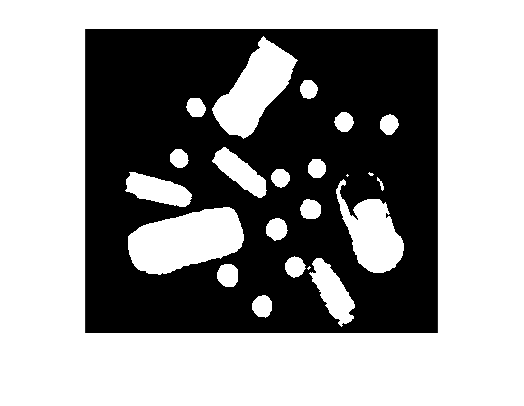


%Vector de valor medio y Matriz de covarianza iniciales
mu_1 = [1, 0.8];
mu_2 = [0.5, 0.9];

Sigma_1 = eye(2);
Sigma_2 = eye(2);

%Acividad 5.1 modifica el siguiente código para que se pueda acutalizar, cuando el vector de valor medio 
% no se modifique en distancia respecto a su valor anterior en 0.1
    figure
    imshow(BW);
    hold on;

    
    %las variables k y l, nos sirven para guardar los patrones x, en sus
    %respectivas clases, x_1, x_2
    k = 1;
    l = 1;
    
    %Funciones de decision
    d_1 = mu_1*Sigma_1*x - 0.5* mu_1*Sigma_1*mu_1';

Unrecognized function or variable 'x'.

    d_2 = mu_2*Sigma_2*x - 0.5* mu_2*Sigma_2*mu_2';
    %Se recorre todo los valores de desicion, de los patrones x
    for j = 1:length(d_1)
        radio(j) = mean([s.MajorAxisLength(j), s.MinorAxisLength(j)])/2;
        if d_1(j) > d_2(j)          % si d_1 > d_2() para un x, entonces x se guarda en x_1
           x_1(:,k) =  x(:,j);
           k = k+1;
           plot(s.Centroid(j,1), s.Centroid(j,2),'b*');
           viscircles(s.Centroid(j,:),radio(j));
        else                        % si d_2 > d_1() para un x, entonces x se guarda en x_1
           x_2(:,l) =  x(:,j);
           l = l+1; 
        end
    end
    hold off;

    %Nuevo centroide
    muNew_1 = sum(x_1')'/length(x_1);
    muNew_2 = sum(x_2')'/length(x_2);


    figure
    %Se trazan los vectores de los patrones, de color rojo para la clase
    %1, y color verde para la clase 2
    plot(x_1(1,:), x_1(2,:), 'Marker',"*",'LineStyle',"none", 'Color','r');        hold on; 
    plot(x_2(1,:), x_2(2,:), 'Marker',"*",'LineStyle',"none", 'Color','g'); 
    xlabel('Circularidad');        ylabel('Excentricidad');
    
    %Se trazan los vectores de valor medio, anterior (+) y actual (o), para observar el desplazamiento 
    % debido al calculo del nuevo vector de valor medui
    plot(mu_1(1), mu_1(2),'Marker',"+",'LineStyle',"none", 'Color','r', 'LineWidth',3);
    plot(muNew_1(1), muNew_1(2),'Marker',"O",'LineStyle',"none", 'Color','r', 'LineWidth',3);
    plot(mu_2(1), mu_2(2),'Marker',"+",'LineStyle',"none", 'Color','g', 'LineWidth',3);
    plot(muNew_2(1), muNew_2(2),'Marker',"O",'LineStyle',"none", 'Color','g', 'LineWidth',3);
    hold off;

    %Se calcula las nuevas matriz de corianza, Sigma_1 y Sigma_2
    SigmaNew_1 = zeros(2);
    for p = 1:length(x_1)
        SigmaNew_1 = SigmaNew_1 + x_1(:,p)*x_1(:,p)';
    end
    SigmaNew_1 = SigmaNew_1/length(x_1)-muNew_1'*muNew_1;
    Sigma_1 = SigmaNew_1;

    SigmaNew_2 = zeros(2);
    for p = 1:length(x_2)
        SigmaNew_2 = SigmaNew_2 + x_2(:,p)*x_2(:,p)';
    end
    SigmaNew_2 = SigmaNew_2/length(x_2)-muNew_2'*muNew_2;
    Sigma_2 = SigmaNew_2;

   

